% Ordnerpfad der Testdaten
folderPath = "G:\Meine Ablage\Master\02_research\Masterarbeit\04_Daten\Testdaten";
% Liste aller CSV-Dateien im Ordner
fileList = dir(fullfile(folderPath, '*.csv'));

TP = 0;
TN = 0;
ges_all = 0;

filt_HDPE = 0;
filt_LDPE = 0;
filt_PET = 0;
filt_PP = 0;
filt_PS = 0;

filt_TP_HDPE = 0;
filt_TP_LDPE = 0;
filt_TP_PET = 0;
filt_TP_PP = 0;
filt_TP_PS = 0;


% Definition der Klassen (Materialien)
classes = {'HDPE', 'LDPE', 'PET', 'PP', 'PS'};

% Erstellen einer leeren Konfusionsmatrix
confusion_matrix = zeros(length(classes));

% Schleife über jede Datei im Ordner
for m = 1:length(fileList)
    integral_values = zeros(1, length(filter_regions));
    % Vollstaendiger Pfad zur aktuellen Datei
    currentFilePath = fullfile(folderPath, fileList(m).name);

    % Material aus Dateiname extrahieren
    fileNameParts = strsplit(fileList(m).name, '_');
    current_material = fileNameParts{1};
    
    % Daten aus aktuellem Dateipfad einlesen
    identData = readmatrix(currentFilePath, 'Delimiter', ';');
    data = identData(:, 2);

    % Funktion erstellen durch Interpolation
    interp_function = @(x) interp1(wavelengths, data, x, 'linear', 'extrap');

    % Berechnung des Integrals fuer jeden Bereich
    for j = 1:length(filter_regions)
        fun = interp_function;
        integral_values(:,j) = integral(fun, filter_regions(j,1), filter_regions(j,2));
    end
    
    % Normierung und Transformation des unbekannten Spektrums
    centeredUnknownSpectrum = zscore(integral_values, 0,2);
    projectedUnknownSpectrum = centeredUnknownSpectrum * coeff(:, 1:3);
    
    % Identifikation ueber kNN-Algorithmus
    mdl = fitcknn(X_pca, y, 'NumNeighbors', 3);
    predictedLabel = predict(mdl, projectedUnknownSpectrum);
    labelClass = predictedLabel;
    
    % ident_material wird je nach erkanntem Material definiert 
    switch labelClass
        case 1
            ident_material = 'HDPE';            
        case 2
            ident_material = 'LDPE';
        case 3
            ident_material = 'PET';
        case 4
            ident_material = 'PP';
        case 5
            ident_material = 'PS';
        otherwise
            error('Invalid labelClass value');
    end

    % Abgleich, ob erkanntes Material dem echten Material entspricht
    switch current_material
        case 'HDPE'
            filt_HDPE = filt_HDPE +1;
            switch labelClass
                case 1
                    filt_TP_HDPE = filt_TP_HDPE +1;  
            end
         case 'LDPE'
            filt_LDPE = filt_LDPE +1;
            switch labelClass        
                case 2
                    filt_TP_LDPE = filt_TP_LDPE +1;             
            end       
          case 'PET'
            filt_PET = filt_PET +1;
            switch labelClass
                case 3
                    filt_TP_PET = filt_TP_PET +1;   
            end
          case 'PP'
            filt_PP = filt_PP +1;
            switch labelClass    
                case 4
                    filt_TP_PP = filt_TP_PP +1;
            end
          case 'PS'
            filt_PS = filt_PS +1;
            switch labelClass  
                case 5
                    filt_TP_PS = filt_TP_PS +1;
            end
    end 

    % Aktualisierung der Konfusionsmatrix basierend auf den vorhergesagten und tatsaechlichen Klassen
    true_class_idx = find(strcmp(classes, current_material));
    predicted_class_idx = find(strcmp(classes, ident_material));
    confusion_matrix(true_class_idx, predicted_class_idx) = confusion_matrix(true_class_idx, predicted_class_idx) + 1;

    if strcmp(ident_material, current_material)
        TP = TP +1;
        ges_all = ges_all +1;
    else
        TN = TN +1;
        ges_all = ges_all +1;
    end
    %fprintf('Verarbeitung von Datei %s abgeschlossen.\n', fileList(i).name);
end

% Berechnung der Genauigkeiten
acc = (TP/ges_all)*100;
acc_HDPE = (filt_TP_HDPE/filt_HDPE)*100;
acc_LDPE = (filt_TP_LDPE/filt_LDPE)*100;
acc_PET = (filt_TP_PET/filt_PET)*100;
acc_PP = (filt_TP_PP/filt_PP)*100;
acc_PS = (filt_TP_PS/filt_PS)*100;

% Ausgabe der Genauigkeiten
fprintf('Es wurde eine Gesamtgenauigkeit von %0.2f%% erreicht.\n', acc)

Es wurde eine Gesamtgenauigkeit von 94.44% erreicht.


fprintf('Die einzelnen Genauigkeiten nach Kunststoffart:\n')

Die einzelnen Genauigkeiten nach Kunststoffart:


fprintf('Genauigkeit HDPE: %0.2f%%\n', acc_HDPE)

Genauigkeit HDPE: 100.00%


fprintf('Genauigkeit LDPE: %0.2f%%\n', acc_LDPE)

Genauigkeit LDPE: 71.43%


fprintf('Genauigkeit PET: %0.2f%%\n', acc_PET)

Genauigkeit PET: 100.00%


fprintf('Genauigkeit PP: %0.2f%%\n', acc_PP)

Genauigkeit PP: 100.00%


fprintf('Genauigkeit PS: %0.2f%%\n', acc_PS)

Genauigkeit PS: 100.00%



% Ausgabe der Konfusionsmatrix
disp('Konfusionsmatrix:');

Konfusionsmatrix:


disp(confusion_matrix);

     7     0     0     0     0
     2     5     0     0     0
     0     0     5     0     0
     0     0     0    10     0
     0     0     0     0     7



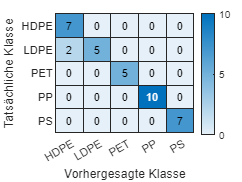

% Plotte die Konfusionsmatrix als Heatmap
heatmap(classes, classes, confusion_matrix);
xlabel('Vorhergesagte Klasse');
ylabel('Tatsächliche Klasse');

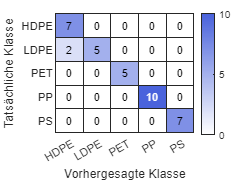


% Anzahl der Vorhersagen in Prozentwerte konvertieren
percent_confusion_matrix = confusion_matrix ./ sum(confusion_matrix, 2) * 100;

% Anzahl der Zwischenschritte festlegen
num_steps = 100; 


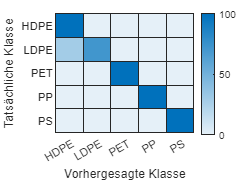

% Plotten der Konfusionsmatrix als Heatmap mit Prozentwerten
heatmap(classes, classes, percent_confusion_matrix);
xlabel('Vorhergesagte Klasse');
ylabel('Tatsächliche Klasse');